# WSHP Models

## 🚀 Initialization

clc; clear all;

% Parent directory
par_dir = pwd;

% Add path to subfunction
addpath(strcat(par_dir,'/matlab_subfunc'));

% Specify the data folder path
data_folder = 'data/';

% Get a list of all files in the data folder
files = dir(fullfile(data_folder, '*.csv'));

## 🧹 Preprocess

% Initialize an empty array of structs
fileData = struct('fileName', {}, ...
                  'error', {}, ...
                  'acc_error', {}, ...
                  'inlet_water_temp', {}, ...
                  'return_air_temp', {}, ...
                  'return_air_hr', {}, ...
                  'sim_zone_temp', {}, ...
                  'wshp_power', {}, ...
                  'sen_load', {}, ...
                  'lat_load', {}, ...
                  'air_cfm', {}, ...
                  'comp_spd', {}, ...
                  'fan_spd', {},...
                  'active_spt', {},...
                  'tstat_spt', {});

% Loop through the file paths
for i = 1:length(files)
    file = files(i).name;
    fprintf('i: %d, file: %s\n', i, file);

    % Get the file path of the selected file
    file_path = fullfile(data_folder, file);

    % Read the csv file
    data = readtable(file_path,"PreserveVariableNames",true);
    
    % Remove rows where 'Simulation Time Step' is <= 300 and >=1260 and missing value
    data = data(data.('Simulation Time Step') > 300 & data.('Simulation Time Step') < 1260, :);
    data = rmmissing(data);
    
    % Filter data
%     wshp_power = data{:, contains(data.Properties.VariableNames, 'WSHP Power')}/1000;   % convert to kW
%     wshp_power_15minavg = movmean(wshp_power, [15*12-1, 0]);
%     data = data(wshp_power_15minavg > 0.15, :);
    
    % Extract columns based on their names or patterns
    simulation_time_step = data.('Simulation Time Step');
    sim_zone_temp = data{:, contains(data.Properties.VariableNames, 'Sim Zone Temp')};
    active_spt = data{:, contains(data.Properties.VariableNames, 'Active Setpoint')};
    inlet_water_temp = data{:, contains(data.Properties.VariableNames, 'Inlet Water Temp')};
    return_air_temp = data{:, contains(data.Properties.VariableNames, 'WSHP Return Air Temp')};
    return_air_hr = data{:, contains(data.Properties.VariableNames, 'WSHP Avg Return HR')};
    wshp_power = data{:, contains(data.Properties.VariableNames, 'WSHP Power')}/1000;   % convert to kW
    sen_load = data{:, contains(data.Properties.VariableNames, 'Meas Sensible Load')};
    lat_load = - data{:, contains(data.Properties.VariableNames, 'Meas Latent Load')};    % sign seems wrong
    air_cfm = data{:, contains(data.Properties.VariableNames, 'WSHP Air Flowrate')};
    fan_spd = data{:, contains(data.Properties.VariableNames, 'Fan Speed')};
    tstat_spt = data{:, contains(data.Properties.VariableNames, 'Sim Cool SP')};
    
    % Calculate error
    error = sim_zone_temp - active_spt;
    
    % Calculate accumulated error
    criteria_series = wshp_power;
    reset_threshold = 0.15;
    acc_error = accumulated_errors(sim_zone_temp, active_spt, criteria_series, reset_threshold);
    
    % Calculate compressor speed ratio
    vdc = compressor_vdc(fan_spd, wshp_power, 0.15);
    comp_spd = comp_spd_ratio(vdc);
    
    % Smooth the data
    min_avg = 15;
    windowSize = min_avg * 12;    
    error_avg = movmean(error, [windowSize-1, 0], "Endpoints", "discard");
    acc_error_avg = movmean(acc_error, [windowSize-1, 0], "Endpoints", "discard");
    inlet_water_temp_avg = movmean(inlet_water_temp, [windowSize-1, 0], "Endpoints", "discard");
    return_air_temp_avg = movmean(return_air_temp, [windowSize-1, 0], "Endpoints", "discard");
    return_air_hr_avg = movmean(return_air_hr, [windowSize-1, 0], "Endpoints", "discard");
    sim_zone_temp_avg = movmean(sim_zone_temp, [windowSize-1, 0], "Endpoints", "discard");
    wshp_power_avg = movmean(wshp_power, [windowSize-1, 0], "Endpoints", "discard");
    sen_load_avg = movmean(sen_load, [windowSize-1, 0], "Endpoints", "discard");
    lat_load_avg = movmean(lat_load, [windowSize-1, 0], "Endpoints", "discard");
    air_cfm_avg = movmean(air_cfm, [windowSize-1, 0], "Endpoints", "discard");  
    comp_spd_avg = movmean(comp_spd, [windowSize-1, 0], "Endpoints", "discard");
    fan_spd_avg = movmean(fan_spd, [windowSize-1, 0], "Endpoints", "discard");
    active_spt_avg = movmean(active_spt, [windowSize-1, 0], "Endpoints", "discard");
    tstat_spt_avg = movmean(tstat_spt, [windowSize-1, 0], "Endpoints", "discard");
    
    % Store smoothed data
    fileData(i).fileName = file;
    fileData(i).error = error_avg; 
    fileData(i).acc_error = acc_error_avg; 
    fileData(i).comp_spd = comp_spd_avg;
    fileData(i).inlet_water_temp = inlet_water_temp_avg; 
    fileData(i).return_air_temp = return_air_temp_avg; 
    fileData(i).return_air_hr = return_air_hr_avg; 
    fileData(i).wshp_power = wshp_power_avg; 
    fileData(i).sen_load = sen_load_avg; 
    fileData(i).lat_load = lat_load_avg; 
    fileData(i).air_cfm = air_cfm_avg; 
    fileData(i).fan_spd = fan_spd_avg;
%     fileData(i).sim_zone_temp = sim_zone_temp_avg;
%     fileData(i).active_spt = active_spt_avg;
%     fileData(i).tstat_spt = tstat_spt_avg;

    % Store data with original sample rate but trimmed
%     fileData(i).error = error(windowSize:end); 
%     fileData(i).acc_error = acc_error(windowSize:end); 
%     fileData(i).comp_spd = comp_spd(windowSize:end);
    fileData(i).sim_zone_temp = sim_zone_temp(windowSize:end);
    fileData(i).active_spt = active_spt(windowSize:end);
    fileData(i).tstat_spt = tstat_spt(windowSize:end);
end

i: 1, file: Test_AtlantaSHiftExtSum_07162023_0005.csv
i: 2, file: Test_AtlantaShiftDefault_061623_1055.csv
i: 3, file: Test_AtlantaShiftSTD2019_04092023_2320.csv
i: 4, file: Test_AtlantaTES_04222023_2302.csv
i: 5, file: Test_Atlanta_Def_MPC_021624_2105.csv
i: 6, file: Test_Atlanta_Default_1hr_110123_1357.csv
i: 7, file: Test_Atlanta_Default_MPC_Pretest_122723_1025.csv
i: 8, file: Test_Atlanta_Default_Random_102923_1331.csv
i: 9, file: Test_Atlanta_Default_random2_102623_2106.csv
i: 10, file: Test_Atlanta_Default_random_102423_1727.csv
i: 11, file: Test_BuffaloShiftDef_06022023_1805.csv
i: 12, file: Test_BuffaloShiftDenseOcc_06142023_2109.csv
i: 13, file: Test_BuffaloShiftExtSum_060323_2005.csv
i: 14, file: Test_BuffaloShiftSTD2019_060723_1026.csv
i: 15, file: Test_BuffaloShiftSaveBehave_06182023_0242.csv
i: 16, file: Test_NewYorkShiftDef_03312023_1837.csv
i: 17, file: Test_NewYorkShiftDenseOcc_04012023_2115.csv
i: 18, file: Test_NewYorkShiftSTD2019_05312023_2327.csv
i: 19, file: Test_T

## 🔎 Visualize data points

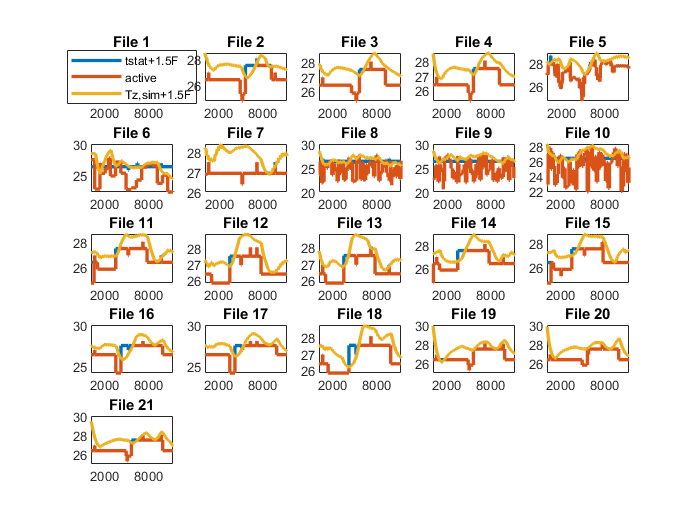

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData) 
    
    % Select data point
    select_data_point = fileData(i).wshp_power;
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
%     plot(select_data_point);
    plot(fileData(i).tstat_spt(1:end)+1.5/1.8, 'LineWidth', 2, 'DisplayName', 'tstat+1.5F');hold on
    plot(fileData(i).active_spt(1:end), 'LineWidth', 2, 'DisplayName', 'active');hold on
    plot([fileData(i).sim_zone_temp(1:end)+1.5/1.8], 'LineWidth', 2, 'DisplayName', 'Tz,sim+1.5F');
%     plot(fileData(i).acc_error);
%     plot(fileData(i).comp_spd);
%     plot(fileData(i).error);
%     scatter(1:numel(fileData(i).error), sort(fileData(i).error), '.');
%     yyaxis left
%     plot(fileData(i).tstat_spt(1:end-1)+1.5/1.8);hold on
%     plot(fileData(i).active_spt(2:end));hold on
% %     plot(fileData(i).active_spt_offset);
%     plot(fileData(i).active_spt); hold on
%     plot(fileData(i).tstat_spt);
%     yyaxis right
%     plot(diff(fileData(i).tstat_spt(1:end-1)+1.5/1.8));
%     plot(fileData(i).sim_zone_temp);
%     plot([diff(fileData(i).comp_spd);0]);hold on
%     plot([1,length(fileData(i).comp_spd)], [0,0]);
    title(sprintf('File %d', i));
    
    if i == 1
        legend('Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(select_data_point)]);
    
end

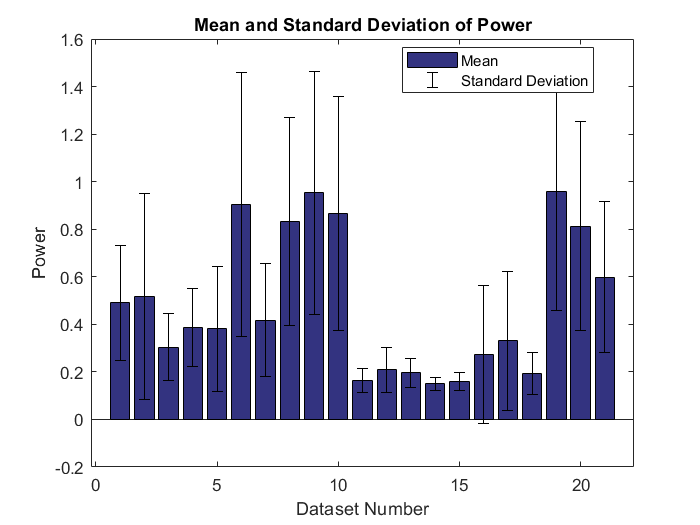


% Statistical metrics 

% Loop through all data files
for i = 1:length(fileData) 
    
    % Select data point
    select_data_point = fileData(i).wshp_power;
    
    % Average
    select_data_point_mean(i) = mean(select_data_point);
    
    % Standard deviation
    select_data_point_std(i) = std(select_data_point);
end

% Plot metrics
figure; % Creates a new figure window

% Create a bar graph for the means
bar(select_data_point_mean, 'FaceColor', [0.2, 0.2, 0.5]);
hold on; % Hold on to plot error bars on top

% Calculate the x positions for the error bars
xPos = 1:length(fileData);

% Add error bars for the standard deviations
errorbar(xPos, select_data_point_mean, select_data_point_std, 'k', 'linestyle', 'none');

% Enhance plot
title('Mean and Standard Deviation of Power');
xlabel('Dataset Number'); % Assuming each dataset corresponds to a number
ylabel('Power');
legend({'Mean', 'Standard Deviation'}, 'Location', 'best');
hold off; % Release the plot hold

## 🏗️ Virtual testbed development

### 🧩 Prepare data

% % Number of files in fileData
% numFiles = length(fileData);
% 
% % Random exclude
% numExcludes = 4;
% excludeIndices = randperm(numFiles, numExcludes);
% 
% % Select data
% excludeIndices = [11];   % Override with manual select
% selectIndex = ~ismember(1:numFiles, excludeIndices);
% selectData = fileData(selectIndex);
selectData = fileData;

% Initialize feature and targets
x1 = [];
x2 = [];
x3 = [];
x4 = [];
x5 = [];
x6 = [];
xy1 = [];
xy2 = [];
y1 = [];
y2 = [];
y3 = [];
y4 = [];

% Combine data from selectData
for i = 1:length(selectData)
    x1 = [x1;selectData(i).error];
    x2 = [x2;selectData(i).acc_error];
    x3 = [x3;selectData(i).inlet_water_temp];
    x4 = [x4;selectData(i).return_air_temp];
    x5 = [x5;selectData(i).return_air_hr];
    x6 = [x6;selectData(i).sim_zone_temp];
    xy1 = [xy1;selectData(i).comp_spd];
    xy2 = [xy2;selectData(i).fan_spd];
    y1 = [y1;selectData(i).wshp_power];
    y2 = [y2;selectData(i).sen_load];
    y3 = [y3;selectData(i).lat_load];
    y4 = [y4;selectData(i).air_cfm];
end

### 🕸️ Visualize data distribution

#### Select data

% x
xval = x1; xval_label = 'Error';
% xval = x2; xval_label = 'Accumulated Error';

% y
% yval = y1; yval_label = 'Power';
yval = x2; yval_label = 'Accumulated Error';

#### Plot

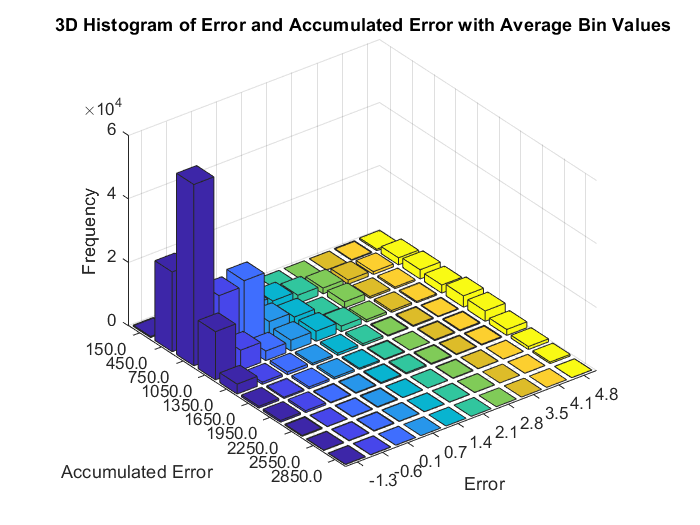

% Create a 2D histogram data
[N, C] = hist3([xval, yval], [10, 10]); % Adjust [10, 10] for different bin sizes

% Plot the 3D histogram using bar3
figure;
bar3Handle = bar3(N);
xlabel(xval_label);
ylabel(yval_label);
zlabel('Frequency');
title(['3D Histogram of ' xval_label ' and ' yval_label ' with Average Bin Values']);

% Set the tick labels to the bin centers, rounded to 1 decimal place
xticks(1:length(C{1}));
xticklabels(arrayfun(@(x) num2str(x, '%.1f'), C{1}, 'UniformOutput', false));
yticks(1:length(C{2}));
yticklabels(arrayfun(@(y) num2str(y, '%.1f'), C{2}, 'UniformOutput', false));

% Limit the x and y axes - set your desired limits here
xlim([0.5 length(C{1})+0.5]); % Limits for x-axis based on the number of bins
ylim([0.5 length(C{2})+0.5]); % Limits for y-axis based on the number of bins

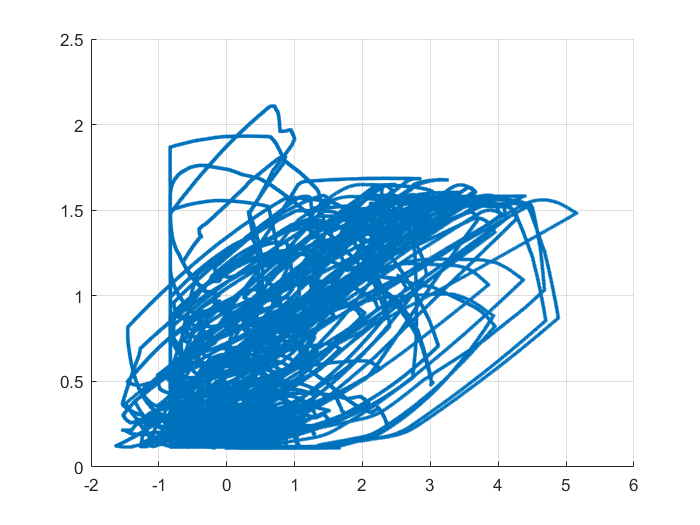






% 2D x1 and y1 distribution
figure;
scatter(x1,y1, '.');
grid on

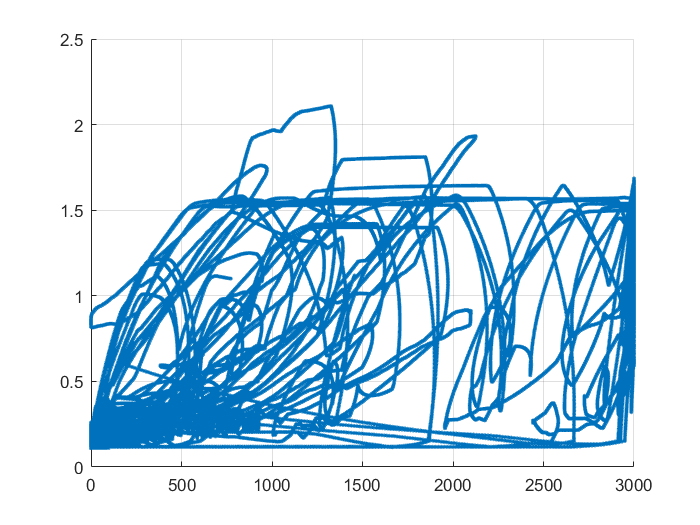


% 2D x2 and y1 distribution
figure;
scatter(x2,y1, '.');
grid on

### 🤖 Power model development

#### 📥 Feature space

% Form feature space
X = [x1,x2,x3,x4,x5];

#### 🔁 Cross validation

% % Define cv partition
% nFolds = 10;
% % cv = cvpartition(size(X, 1), 'KFold', nFolds);
% 
% % Determine the number of observations per fold (this example assumes divisibility for simplicity)
% obsPerFold = floor(size(X, 1) / nFolds);
% 
% % Initialize array for RMSE values
% rmseVals = zeros(nFolds, 1);
% 
% % Enable parallel computing
% if isempty(gcp('nocreate')) % If no parallel pool, create a new one
%     parpool;
% end
% 
% % Parallel for loop for cross-validation
% parfor i = 1:nFolds
% %     trainIdx = cv.training(i);
% %     testIdx = cv.test(i);
% 
%     % Define the indices for the test set
%     testIdx = ((i-1)*obsPerFold + 1):(i*obsPerFold);
%     
%     % Define the indices for the training set: all data points no in the test set
%     trainIdx = setdiff(1:size(X, 1), testIdx) 
%     
%     % Train the model
%     power_model = TreeBagger(50, X(trainIdx,:), y1(trainIdx), 'Method', 'regression');
%     
%     % Predict on validation set
%     predictions = predict(power_model, X(testIdx,:));
%     
%     % Calculate RMSE for this fold
%     rmseVals(i) = sqrt(mean((predictions - y1(testIdx)).^2));
% end
% 
% % Compute average RMSE
% averageRMSE = mean(rmseVals);
% 
% % Display results
% disp('RMSE for each fold:');
% disp(rmseVals);
% disp(['Average RMSE across all folds: ', num2str(averageRMSE)]);

#### 🌳 Train a Random Forest Model

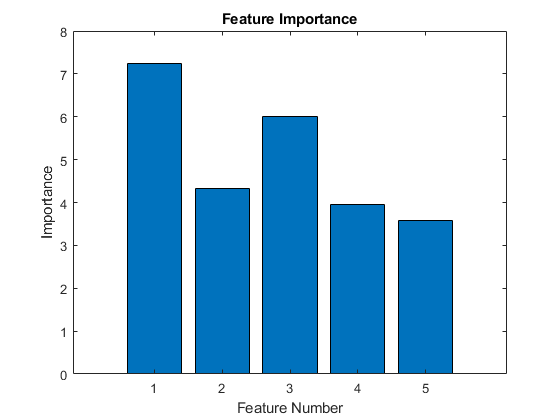

% Train model using selectData
power_model = TreeBagger(50, X, y1, 'Method', 'regression', "OOBPrediction", "on", "OOBPredictorImportance", "on");

% Accessing the feature importance
featureImportance = power_model.OOBPermutedVarDeltaError;

% Displaying the feature importance
figure;
bar(featureImportance);
xlabel('Feature Number');
ylabel('Importance');
title('Feature Importance');


% Save the model
save('saved_models/wshp_power_model.mat','power_model')

#### 🧬 Train a MARS model

% % Build MARS model
% trainParams = aresparams(20); % Reducing from the default to speed up training
% power_model = aresbuild(X, y1, trainParams);
% 
% 
% 
% % Save the model
% save('saved_models/wshp_power_model.mat','power_model');

#### 📊 Visualize feature impact

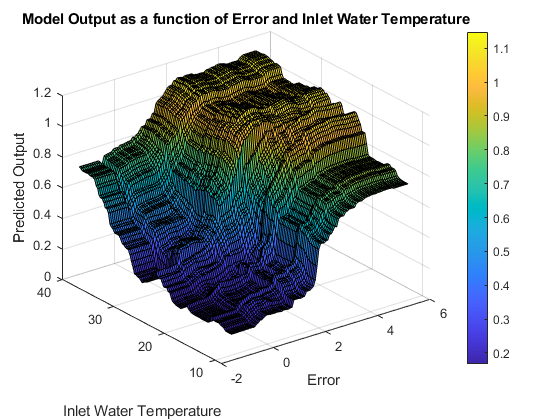

% Assuming X is your features matrix and y1 is the target vector

% Step 1: Create a grid of values for x1 and x3
x1_range = linspace(min(X(:,1)), max(X(:,1)), 100);
x3_range = linspace(min(X(:,3)), max(X(:,3)), 100);
[x1_grid, x3_grid] = meshgrid(x1_range, x3_range);

% Step 2: Prepare the data for prediction
% For simplicity, we'll use the median values for the other features (x2, x4, x5)
x2_median = median(X(:,2));
x4_median = median(X(:,4));
x5_median = median(X(:,5));

% Combine the grid with the medians of other features
predict_data = [x1_grid(:), repmat(x2_median, numel(x1_grid), 1), x3_grid(:), repmat(x4_median, numel(x1_grid), 1), repmat(x5_median, numel(x1_grid), 1)];

% Predict model output for the grid
predicted_output = predict(power_model, predict_data);

% Step 3: Plot the results
% Reshape the predicted output to match the grid size for plotting
predicted_output_reshaped = reshape(predicted_output, size(x1_grid));

% 3D surface plot
figure;
surf(x1_grid, x3_grid, predicted_output_reshaped);
xlabel('Error');
ylabel('Inlet Water Temperature');
zlabel('Predicted Output');
title('Model Output as a function of Error and Inlet Water Temperature');
colorbar; % Adds a color bar to indicate the scale of predicted output

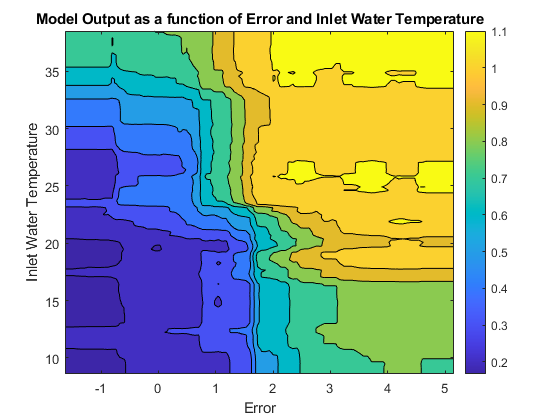


% Alternatively, for a 2D contour plot
figure;
contourf(x1_grid, x3_grid, predicted_output_reshaped);
xlabel('Error');
ylabel('Inlet Water Temperature');
title('Model Output as a function of Error and Inlet Water Temperature');
colorbar; % Adds a color bar to indicate the scale of predicted output

#### ✍️ Manual validation

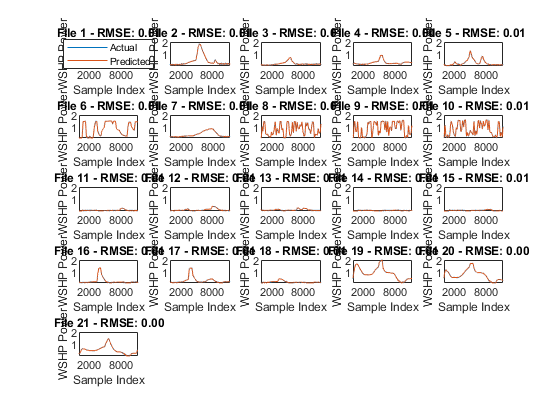

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); 
numRows = ceil(numFiles / numCols); 

% Variables to find the global min and max for y-axis
globalMin = Inf;
globalMax = -Inf;

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error,...
             fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_hr];
   
    % Actual target value
    act = fileData(i).wshp_power;
    
    % Predicted target value
    pred = predict(power_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); % Actual in blue
    hold on;
    plot(pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('WSHP Power');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);

    % Update global min and max
    currentMin = min([act; pred]);
    currentMax = max([act; pred]);
    globalMin = min(globalMin, currentMin);
    globalMax = max(globalMax, currentMax);
    
end

% Second pass: Set the global y-axis limits for all subplots
for i = 1:numFiles
    subplot(numRows, numCols, i);
    ylim([globalMin, globalMax]);
end

### 🤖 Sensible load model development

#### 📥 Feature space

% Form feature space
X = [x1,x2,x3,x4,x5];

#### 🌳 Train a Random Forest Model

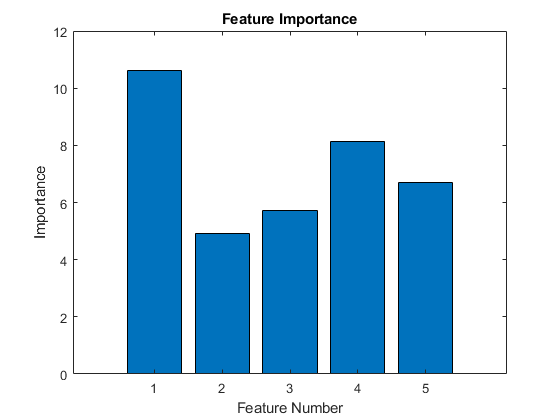

% Train model using selectData
sen_load_model = TreeBagger(50, X, y2, 'Method', 'regression', "OOBPrediction", "on", "OOBPredictorImportance", "on");

% Accessing the feature importance
featureImportance = sen_load_model.OOBPermutedVarDeltaError;

% Displaying the feature importance
figure;
bar(featureImportance);
xlabel('Feature Number');
ylabel('Importance');
title('Feature Importance');


% Save the model
save('saved_models/wshp_sen_load_model.mat','sen_load_model')

#### 📊 Visualize feature impact

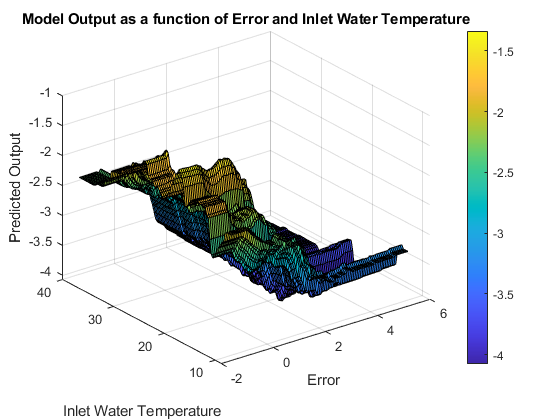

% Assuming X is your features matrix and y1 is the target vector

% Step 1: Create a grid of values for x1 and x3
x1_range = linspace(min(X(:,1)), max(X(:,1)), 100);
x3_range = linspace(min(X(:,3)), max(X(:,3)), 100);
[x1_grid, x3_grid] = meshgrid(x1_range, x3_range);

% Step 2: Prepare the data for prediction
% For simplicity, we'll use the median values for the other features (x2, x4, x5)
x2_median = median(X(:,2));
x4_median = median(X(:,4));
x5_median = median(X(:,5));

% Combine the grid with the medians of other features
predict_data = [x1_grid(:), repmat(x2_median, numel(x1_grid), 1), x3_grid(:), repmat(x4_median, numel(x1_grid), 1), repmat(x5_median, numel(x1_grid), 1)];

% Predict model output for the grid
predicted_output = predict(sen_load_model, predict_data);

% Step 3: Plot the results
% Reshape the predicted output to match the grid size for plotting
predicted_output_reshaped = reshape(predicted_output, size(x1_grid));

% 3D surface plot
figure;
surf(x1_grid, x3_grid, predicted_output_reshaped);
xlabel('Error');
ylabel('Inlet Water Temperature');
zlabel('Predicted Output');
title('Model Output as a function of Error and Inlet Water Temperature');
colorbar; % Adds a color bar to indicate the scale of predicted output

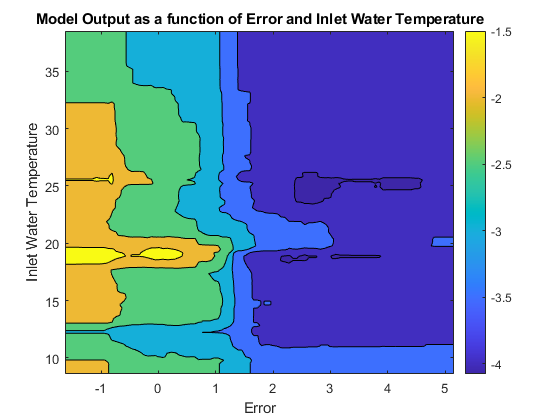


% Alternatively, for a 2D contour plot
figure;
contourf(x1_grid, x3_grid, predicted_output_reshaped);
xlabel('Error');
ylabel('Inlet Water Temperature');
title('Model Output as a function of Error and Inlet Water Temperature');
colorbar; % Adds a color bar to indicate the scale of predicted output

#### ️✍️ Manual validation

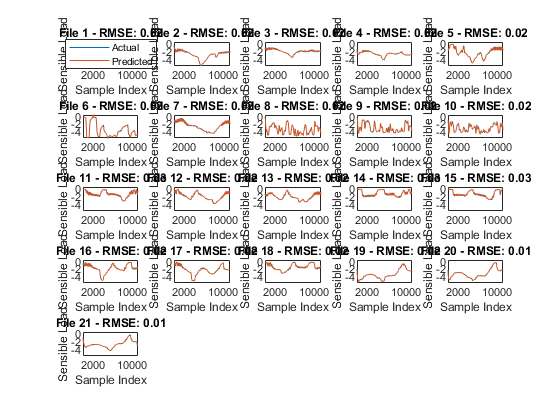

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); 
numRows = ceil(numFiles / numCols); 

% Variables to find the global min and max for y-axis
globalMin = Inf;
globalMax = -Inf;

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error,...
             fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_hr];
   
    % Actual target value
    act = fileData(i).sen_load;
    
    % Predicted target value
    pred = predict(sen_load_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); % Actual in blue
    hold on;
    plot(pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('Sensible Load');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);

    % Update global min and max
    currentMin = min([act; pred]);
    currentMax = max([act; pred]);
    globalMin = min(globalMin, currentMin);
    globalMax = max(globalMax, currentMax);
    
end

% Second pass: Set the global y-axis limits for all subplots
for i = 1:numFiles
    subplot(numRows, numCols, i);
    ylim([globalMin, globalMax]);
end

### 🤖 Latent load model development

#### 📥 Feature space

% Form feature space
X = [x1,x2,x3,x4,x5];

#### 🌳 Train a Random Forest Model

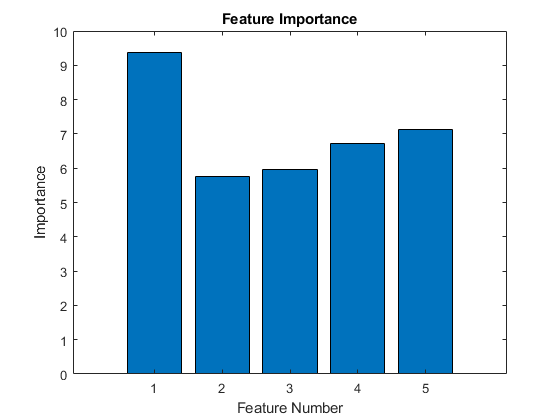

% Train model using selectData
lat_load_model = TreeBagger(50, X, y3, 'Method', 'regression', "OOBPrediction", "on", "OOBPredictorImportance", "on");

% Accessing the feature importance
featureImportance = lat_load_model.OOBPermutedVarDeltaError;

% Displaying the feature importance
figure;
bar(featureImportance);
xlabel('Feature Number');
ylabel('Importance');
title('Feature Importance');


% Save the model
save('saved_models/wshp_lat_load_model.mat','lat_load_model')

#### ️✍️ Manual validation

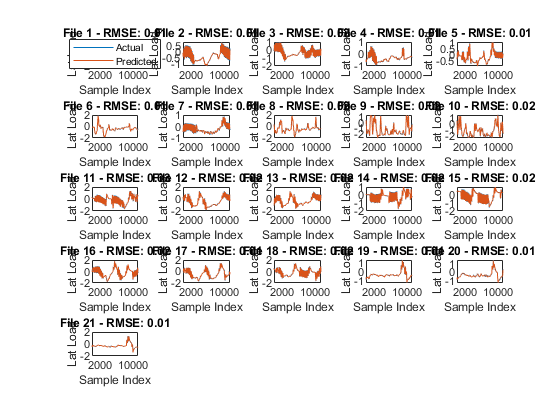

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error,...
             fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_hr];
   
    % Actual target value
    y3_act = fileData(i).lat_load;
    
    % Predicted target value
    y3_pred = predict(lat_load_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((y3_act - y3_pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(y3_act); % Actual in blue
    hold on;
    plot(y3_pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('Lat Load');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(y3_act)]);
    
end

### 🤖 Airflow model development

#### 📥 Feature space

% Form feature space
X = [x1,x2];

#### 🌳 Train a Random Forest Model

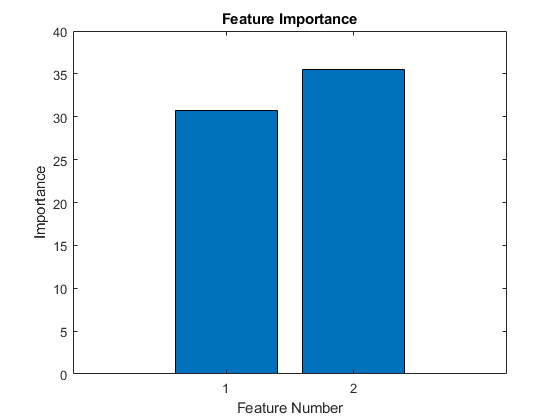

% Train model using selectData
airflow_model = TreeBagger(50, X, y4, 'Method', 'regression', "OOBPrediction", "on", "OOBPredictorImportance", "on");

% Accessing the feature importance
featureImportance = airflow_model.OOBPermutedVarDeltaError;

% Displaying the feature importance
figure;
bar(featureImportance);
xlabel('Feature Number');
ylabel('Importance');
title('Feature Importance');


% Save the model
save('saved_models/wshp_airflow_model.mat','airflow_model')

#### ️✍️ Manual validation

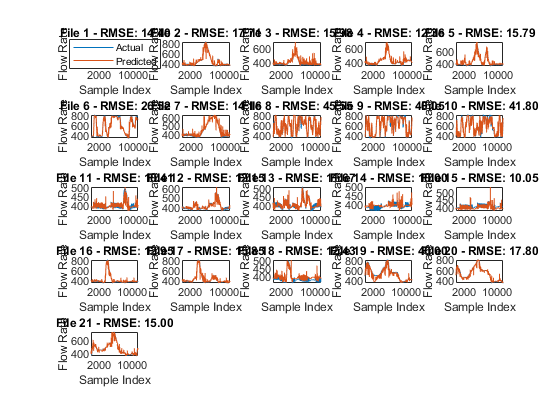

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error];
   
    % Actual target value
    y4_act = fileData(i).air_cfm;
    
    % Predicted target value
    y4_pred = predict(airflow_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((y4_act - y4_pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(y4_act); % Actual in blue
    hold on;
    plot(y4_pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('Flow Rate');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(y4_act)]);
    
end

### 🤖 Compressor speed model development

#### 📥 Feature space

% Form feature space
X = [x1,x2];

#### 🌳 Train a Random Forest model

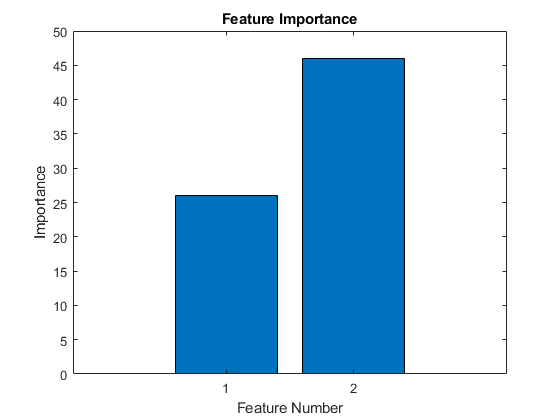

% Train model using selectData
comp_spd_model = TreeBagger(50, X, xy1, 'Method', 'regression', "OOBPrediction", "on", "OOBPredictorImportance", "on");

% Accessing the feature importance
featureImportance = comp_spd_model.OOBPermutedVarDeltaError;

% Displaying the feature importance
figure;
bar(featureImportance);
xlabel('Feature Number');
ylabel('Importance');
title('Feature Importance');


% Save the model
save('saved_models/wshp_comp_spd_model.mat','comp_spd_model')

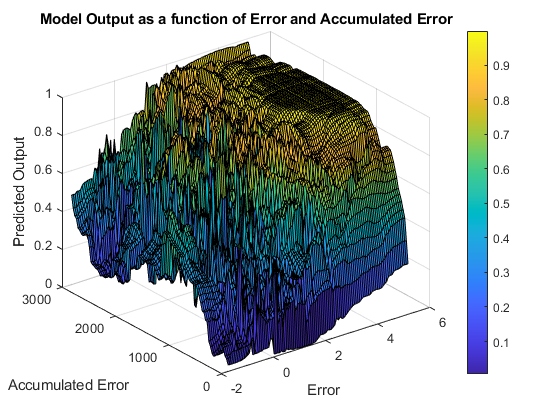

% Assuming X is your features matrix and y1 is the target vector

% Step 1: Create a grid of values for x1 and x2
x1_range = linspace(min(X(:,1)), max(X(:,1)), 100);
x2_range = linspace(min(X(:,2)), max(X(:,2)), 100);
[x1_grid, x2_grid] = meshgrid(x1_range, x2_range);


% Combine the grid with the medians of other features
predict_data = [x1_grid(:), x2_grid(:)];

% Predict model output for the grid
predicted_output = predict(comp_spd_model, predict_data);

% Step 3: Plot the results
% Reshape the predicted output to match the grid size for plotting
predicted_output_reshaped = reshape(predicted_output, size(x1_grid));

% 3D surface plot
figure;
surf(x1_grid, x2_grid, predicted_output_reshaped);
xlabel('Error');
ylabel('Accumulated Error');
zlabel('Predicted Output');
title('Model Output as a function of Error and Accumulated Error');
colorbar; % Adds a color bar to indicate the scale of predicted output

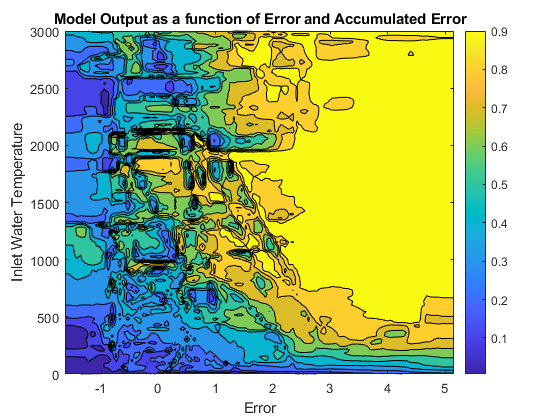


% Alternatively, for a 2D contour plot
figure;
contourf(x1_grid, x2_grid, predicted_output_reshaped);
xlabel('Error');
ylabel('Inlet Water Temperature');
title('Model Output as a function of Error and Accumulated Error');
colorbar; % Adds a color bar to indicate the scale of predicted output

#### ️✍️ Manual validation

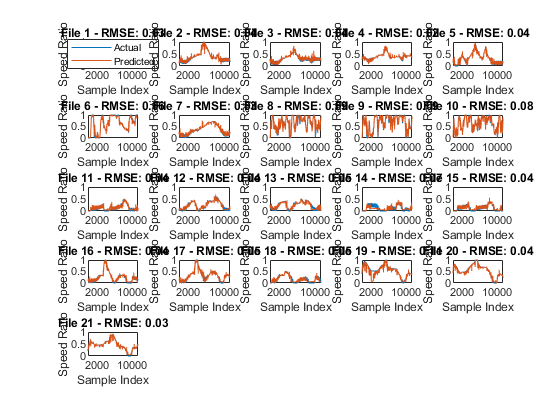

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); 
numRows = ceil(numFiles / numCols); 

% Variables to find the global min and max for y-axis
globalMin = Inf;
globalMax = -Inf;

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error];
         
    % Actual target value
    act = fileData(i).comp_spd;
    
    % Predicted target value
    pred = predict(comp_spd_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); % Actual in blue
    hold on;
    plot(pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('Speed Ratio');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);

    % Update global min and max
    currentMin = min([act; pred]);
    currentMax = max([act; pred]);
    globalMin = min(globalMin, currentMin);
    globalMax = max(globalMax, currentMax);
    
end

% Second pass: Set the global y-axis limits for all subplots
for i = 1:numFiles
    subplot(numRows, numCols, i);
    ylim([globalMin, globalMax]);
end

### 🤖 Compressor speed to power model development 

#### 📥 Feature space

% Form feature space
X = [x3, x4, x5, xy1];

#### 📈 Train a Linear Regression model

% Train model using selectData
compspd2power_model = fitlm(X, y1, 'quadratic');

% Save the model
save('saved_models/wshp_compspd2power_model.mat','compspd2power_model')

#### ️✍️ Manual validation

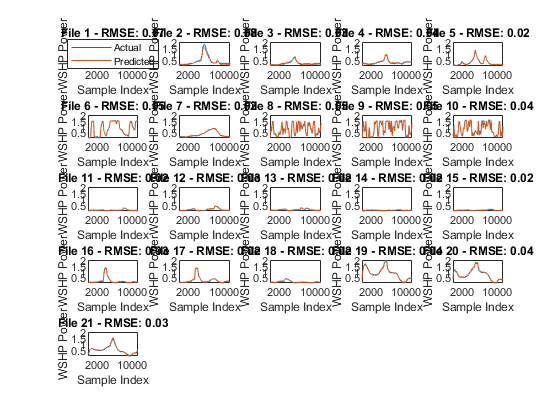

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); 
numRows = ceil(numFiles / numCols); 

% Variables to find the global min and max for y-axis
globalMin = Inf;
globalMax = -Inf;

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_hr,...
             fileData(i).comp_spd];
         
    % Actual target value
    act = fileData(i).wshp_power;
    
    % Predicted target value
    pred = predict(compspd2power_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); 
    hold on;
    plot(pred);
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('WSHP Power');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);

    % Update global min and max
    currentMin = min([act; pred]);
    currentMax = max([act; pred]);
    globalMin = min(globalMin, currentMin);
    globalMax = max(globalMax, currentMax);
    
end

% Second pass: Set the global y-axis limits for all subplots
for i = 1:numFiles
    subplot(numRows, numCols, i);
    ylim([globalMin, globalMax]);
end

#### ✍️ Manual validation (2-step)

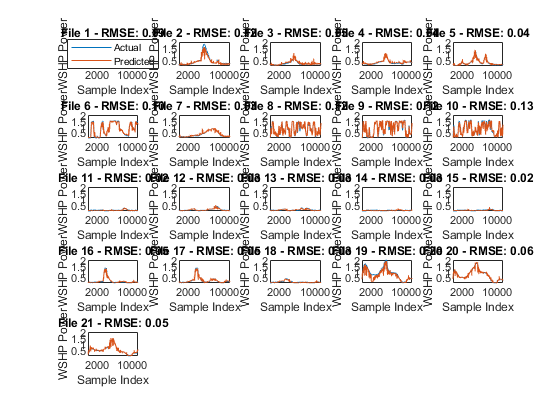

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); 
numRows = ceil(numFiles / numCols); 

% Variables to find the global min and max for y-axis
globalMin = Inf;
globalMax = -Inf;

% Loop through all data files
for i = 1:length(fileData)
    
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error];
         
    % Predicted middle variable
    xy1_pred = predict(comp_spd_model, X_val);
    
    % Features
    X_val = [fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_hr,...
             xy1_pred];
         
    % Actual target value
    act = fileData(i).wshp_power;
    
    % Predicted target value
    pred = predict(compspd2power_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); 
    hold on;
    plot(pred);
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('WSHP Power');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);

    % Update global min and max
    currentMin = min([act; pred]);
    currentMax = max([act; pred]);
    globalMin = min(globalMin, currentMin);
    globalMax = max(globalMax, currentMax);
    
end

% Second pass: Set the global y-axis limits for all subplots
for i = 1:numFiles
    subplot(numRows, numCols, i);
    ylim([globalMin, globalMax]);
end

### 🤖 Compressor speed to sensible capacity model development 

#### 📥 Feature space

% Form feature space
X = [x3, x4, x5, xy1];
% X = [x3, x4, xy1];

#### 📈 Train a Linear Regression model

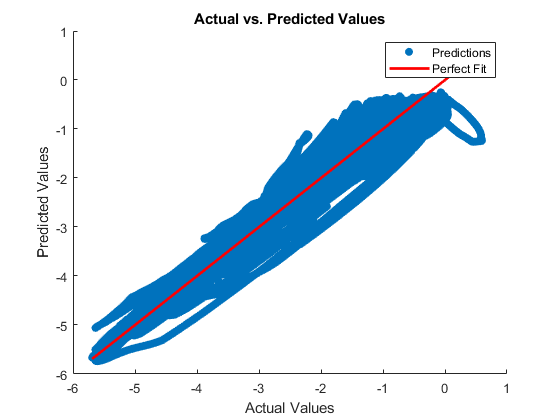

% Train model using selectData
compspd2sen_model = fitlm(X, y2, 'quadratic');

% Save the model
save('saved_models/wshp_compspd2sen_model.mat','compspd2sen_model')

predictedValues = predict(compspd2sen_model, X);
figure; % Create a new figure
scatter(y2, predictedValues, 'filled');
hold on; % Hold on to add more to the plot
plot(y2, y2, 'r', 'LineWidth', 2); % Add a reference line
title('Actual vs. Predicted Values');
xlabel('Actual Values');
ylabel('Predicted Values');
legend('Predictions', 'Perfect Fit');
hold off; % Release the plot 

#### ️✍️ Manual validation

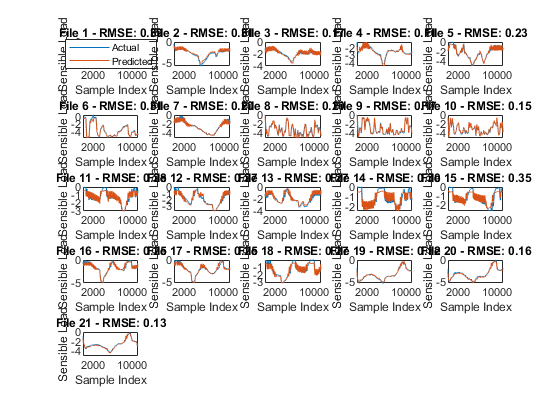

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_hr,...
             fileData(i).comp_spd];
  
    % Actual target value
    act = fileData(i).sen_load;
    
    % Predicted target value
    pred = predict(compspd2sen_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); 
    hold on;
    plot(pred);
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('Sensible Load');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);
    
end

### 🤖 Compressor speed to latent capacity model development 

#### 📥 Feature space

% Form feature space
X = [x3, x4, x5, xy1];

#### 📈 Train a Linear Regression model

% Train model using selectData
compspd2lat_model = fitlm(X, y3, 'quadratic');

% Save the model
save('saved_models/wshp_compspd2lat_model.mat','compspd2lat_model')

#### ️✍️ Manual validation

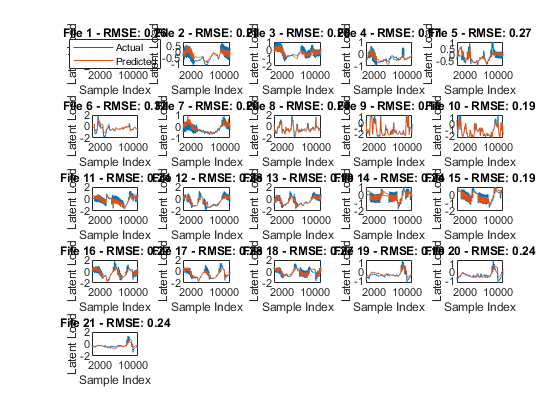

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_hr,...
             fileData(i).comp_spd];
   
    % Actual target value
    act = fileData(i).lat_load;
    
    % Predicted target value
    pred = predict(compspd2lat_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); 
    hold on;
    plot(pred);
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('Latent Load');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);
    
end

### 🤖 Fan speed model development

#### 📥 Feature space

% Form feature space
X = [x1,x2];

#### 🌳 Train a Random Forest Model

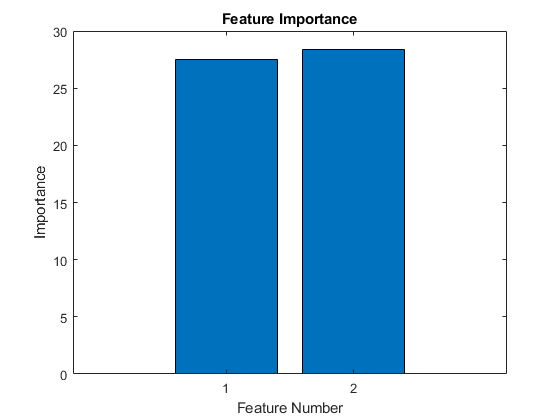

% Train model using selectData
fan_spd_model = TreeBagger(50, X, xy2, 'Method', 'regression', "OOBPrediction", "on", "OOBPredictorImportance", "on");

% Accessing the feature importance
featureImportance = fan_spd_model.OOBPermutedVarDeltaError;

% Displaying the feature importance
figure;
bar(featureImportance);
xlabel('Feature Number');
ylabel('Importance');
title('Feature Importance');


% Save the model
save('saved_models/wshp_fan_spd_model.mat','fan_spd_model')

#### ️✍️ Manual validation

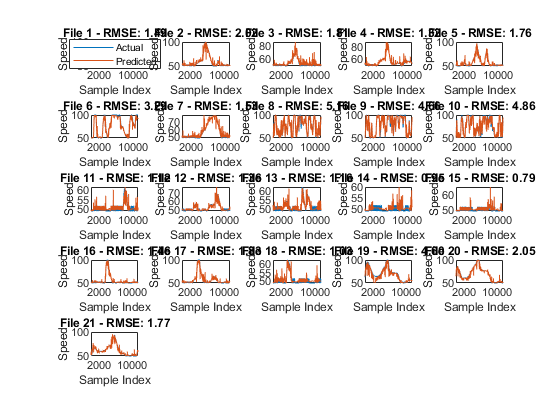

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error];
         
    % Actual target value
    act = fileData(i).fan_spd;
    
    % Predicted target value
    pred = predict(fan_spd_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); % Actual in blue
    hold on;
    plot(pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('Speed');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);
    
end

### 🤖 Fan speed to CFM model development

#### 📥 Feature space

% Form feature space
X = [xy2];

#### 📈 Train a Linear Regression model

% Train model using selectData
fanspd2cfm_model = fitlm(X, y4, 'Intercept', false);

% Save the model
save('saved_models/wshp_fanspd2cfm_model.mat','fanspd2cfm_model')

#### ️✍️ Manual validation

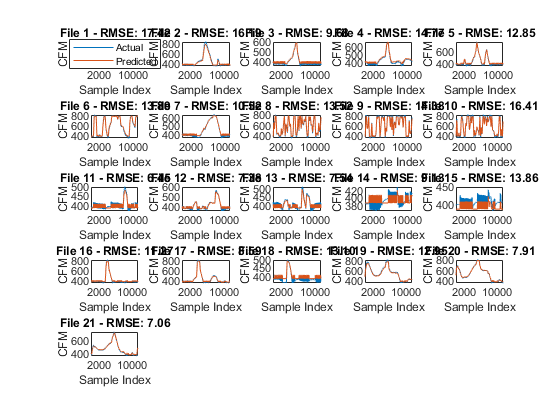

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).fan_spd];
   
    % Actual target value
    act = fileData(i).air_cfm;
    
    % Predicted target value
    pred = predict(fanspd2cfm_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((act - pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(act); % Actual in blue
    hold on;
    plot(pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('CFM');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(act)]);
    
end